clear
addpath('..\..\utilities');
nodepos = load('input\Np.mat').Np;
shearrates = load('input\Shearrate.mat').SRnode;
shearrates(shearrates(:, :) == -1e+30) = 0;
temps = load('input\Tnode.mat').Tnode;
fillstatus = load('input\Fillstatus.mat').Fillstatus;
connectednodes = load('input\connectedNodes.mat').connectedNodes;
connectedelements = load('input\connectedElements.mat').connectedElements;

meshrefiner = meshRefiner;
easyvisualizer = easyVisualizer;
udmwriter = udmWriter;

% Mapping the shearrates and temperatures at the nodes to the elements
elementnodeids = connectednodes + 1; % +1 so that indexing will work
elementshearrates = meshrefiner.getElementValues(elementnodeids, shearrates);
elementtemps = meshrefiner.getElementValues(elementnodeids, temps);
elementnodesfilled = meshrefiner.getElementValues(elementnodeids, fillstatus);

% Calculating shearrate and temperature differences within the elements
sheardiffs = meshrefiner.calcElementDiffs(elementshearrates);
tempdiffs = meshrefiner.calcElementDiffs(elementtemps);

% Calculating element fill status
elementfillstatus = meshrefiner.calcElementFillstatus(elementnodesfilled);

% Calculating highdiffelements and remeshing
[highsheardiffs, normalsheardiffs, highsheardiffsbytimestep] = meshrefiner.calcHighDiffElements(elementfillstatus, sheardiffs, 3);
tic
[newnodepos, newelementnodeids, affectedelements] = meshrefiner.createNewMeshMultiNode(nodepos, elementnodeids, highsheardiffs);
toc

Elapsed time is 9.707510 seconds.


% Writing new udm file
tic
udmwriter.createUDM(newnodepos, newelementnodeids, "outputs\u_strukt_suritett.udm");
toc

Elapsed time is 15.007824 seconds.



[newnodepos_moved, newelementnodeids_moved] = meshrefiner.createNewMeshOneNode(highsheardiffs, shearrates, elementnodeids, nodepos, true);
udmwriter.createUDM(newnodepos_moved, newelementnodeids_moved, "outputs\u_strukt_suritett_eltolt.udm")

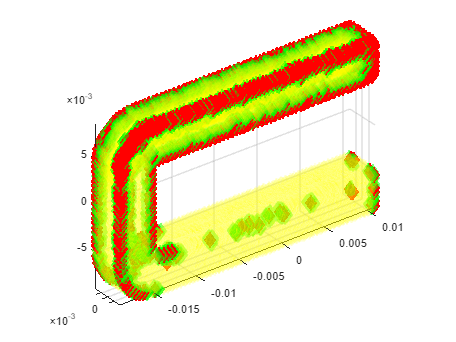

% Visualizations
elementcoordinates = easyvisualizer.getElementCoordinates(elementnodeids, nodepos);
easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs, normalsheardiffs, affectedelements)

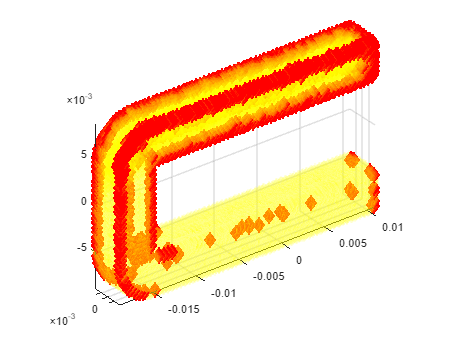

easyvisualizer.plotElementsToRefine(elementcoordinates, highsheardiffs, normalsheardiffs, 0)

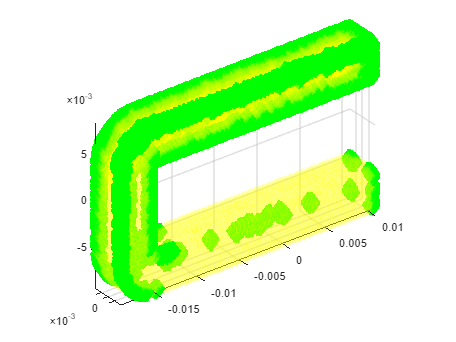

newelementcoordinates = easyvisualizer.getElementCoordinates(newelementnodeids, newnodepos);
easyvisualizer.plotNewElements(elementnodeids, newelementnodeids, affectedelements, newelementcoordinates);